`Rozkład Ch-kwadrat`

`Ciąg niezależnych zmiennych losowych `$Z_1$, $Z_2$, ...., $Z_k$

` z których każdy ma rozkład Gaussa (Normalny) - N(0,1), wówczas`


$$\chi^2 =\sum_{i=1}^k Z_i^2$$


ma rozkład ch-kwadrat z liczbą stopni swobody równą $k$.

Parametry rozkładu chi-kwadrat:

- wartość oczekiwana (średnia): $E\left(\chi^2 \right)=k$,

- wariancja: $D^2 \left(\chi^2 \right)$=2k,

- odchylenie standardowe: $D\left(\chi^2 \right)=\sqrt{2k}\ldotp$

[[wiki]::rozkład Chi kwadrat](https://pl.wikipedia.org/wiki/Rozk%C5%82ad_chi_kwadrat)

[[wiki]:: liczba stopni swobody](https://pl.wikipedia.org/wiki/Liczba_stopni_swobody_(statystyka))

**Liczba stopni swobody**, **df** (*degrees of freedom*) – liczba niezależnych wyników [obserwacji](https://pl.wikipedia.org/wiki/Obserwacja_statystyczna) pomniejszona o liczbę związków, które łączą te wyniki ze sobą (df=k)

Funkcja **chi2pdf  **[[matlab]::chi2pdf](https://www.mathworks.com/help/releases/R2020a/stats/chi2pdf.html) - rozkład gęstości prawdopodobieństwa (*Chi-square probability density function)*

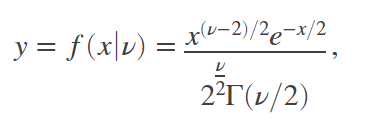

clear all
close all
clc
clearvars

k1=3     %liczba stopni swobody

k1 = 3

k2=10    %inna liczba stopni swobody

k2 = 10

k3=18    %inna liczba stopni swobody

k3 = 18

y=0:0.1:3*k2

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


           
chi2a = chi2pdf(y,k1)

chi2a =          0    0.1200    0.1614    0.1881    0.2066    0.2197    0.2289    0.2352    0.2392    0.2413    0.2420    0.2414    0.2398    0.2375    0.2344    0.2308    0.2267    0.2223    0.2176    0.2127    0.2076    0.2023    0.1970    0.1916    0.1861    0.1807    0.1753    0.1699    0.1646    0.1594    0.1542    0.1491    0.1441    0.1392    0.1344    0.1297    0.1251    0.1207    0.1163    0.1121    0.1080    0.1040    0.1001    0.0964    0.0927    0.0892    0.0858    0.0825    0.0793    0.0762


chi2b = chi2pdf(y,k2)

chi2b =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0005    0.0008    0.0011    0.0015    0.0019    0.0025    0.0031    0.0038    0.0046    0.0056    0.0066    0.0077    0.0089    0.0102    0.0115    0.0130    0.0146    0.0162    0.0179    0.0197    0.0216    0.0235    0.0255    0.0276    0.0297    0.0318    0.0340    0.0362    0.0384    0.0406    0.0429    0.0451    0.0474    0.0496    0.0519    0.0541    0.0563    0.0585    0.0606    0.0627    0.0648


chi2c = chi2pdf(y,k3)

chi2c =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0014



figure(1)
plot(y,chi2a,y,chi2b,y,chi2c,'LineWidth',2)
hold on
grid on
title('Funkcja gęstości prawdopodobieństwa (pdf) rozkładu Chi-kwadrat')
xlabel('Y','Interpreter','latex')
ylabel('pdf','Interpreter','latex')
legend({'k=3','k=10','k=18'},'Location','northeast')


Dystrybuanta - funkcja [chi2cdf](https://www.mathworks.com/help/releases/R2020a/stats/chi2cdf.html) (*Chi-square cumulative distribution function*)

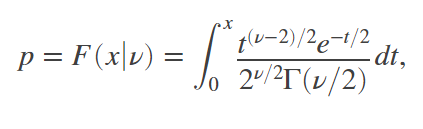

Wizualizacja dystrybuanty

k=3     %liczba stopni swobody

k = 3


y=0:0.1:5*k

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


           
chi2 = chi2cdf(y,k)

chi2 =          0    0.0082    0.0224    0.0400    0.0598    0.0811    0.1036    0.1268    0.1505    0.1746    0.1987    0.2229    0.2470    0.2709    0.2945    0.3177    0.3406    0.3631    0.3851    0.4066    0.4276    0.4481    0.4681    0.4875    0.5064    0.5247    0.5425    0.5598    0.5765    0.5927    0.6084    0.6235    0.6382    0.6524    0.6660    0.6792    0.6920    0.7043    0.7161    0.7275    0.7385    0.7491    0.7593    0.7692    0.7786    0.7877    0.7965    0.8049    0.8130    0.8207



figure(2)
plot(y,chi2,'LineWidth',2)
hold on
grid on
title('Dystrybuanta (cdf) rozkładu Chi-kwadrat')
xlabel('Y','Interpreter','latex')
ylabel('cdf','Interpreter','latex')


Dopełnienie do 1

chi2u = chi2cdf(y,k,'upper')

chi2u =     1.0000    0.9918    0.9776    0.9600    0.9402    0.9189    0.8964    0.8732    0.8495    0.8254    0.8013    0.7771    0.7530    0.7291    0.7055    0.6823    0.6594    0.6369    0.6149    0.5934    0.5724    0.5519    0.5319    0.5125    0.4936    0.4753    0.4575    0.4402    0.4235    0.4073    0.3916    0.3765    0.3618    0.3476    0.3340    0.3208    0.3080    0.2957    0.2839    0.2725    0.2615    0.2509    0.2407    0.2308    0.2214    0.2123    0.2035    0.1951    0.1870    0.1793


plot(y,chi2u,'LineWidth',2)
legend({'cdf','upper'},'Location','northeast')


Rozkład ch-kwadrat przykład:

Zmienna losowa $\chi^2$ ma rozkład chi-kwadrat z liczbą stopni swobody 18. Oblicz prawdopodobienstwo:

- 
$$P\left(\chi^2 <9,2\right)$$
 

y1=9.2

y1 = 9.2000

k=18

k = 18

p1 = chi2cdf(y1,k)

p1 = 0.0451

wizualizacja

k=18                 %liczba stopni swobody

k = 18

y=0:0.1:3*k

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



chi2 = chi2pdf(y,k)

chi2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0014



figure(3)
plot(y,chi2,'LineWidth',2)
hold on
grid on
title('Funkcja gęstości prawdopodobieństwa (pdf) rozkładu Chi-kwadrat')
xlabel('Y','Interpreter','latex')
ylabel('pdf','Interpreter','latex')

xticks(y1)


wizualizacja

Wizualizacja i wypełnienie pola powierzchni pod krzywą rozkładu Chi-kwadrat

Użycie funkcji: [line](https://www.mathworks.com/help/releases/R2020a/matlab/ref/line.html) oraz [area](https://www.mathworks.com/help/releases/R2020a/matlab/ref/area.html)

hold on
a = [y1 y1]

a =     9.2000    9.2000


b = [0 chi2pdf(y1,k)]

b =          0    0.0250


plot(a(2),b(2),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

t =0:0.01:y1

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


chi2_p1 = chi2pdf(t,k);
area(t,chi2_p1 ,'FaceColor','g');
 

- 
$$P\left(\chi^2 \ge 20,3\right)$$
 

y2=20.3

y2 = 20.3000

k=18

k = 18

p2 = 1-chi2cdf(y2,k)

p2 = 0.3162

Inne wywołanie funkcji **chi2cdf**

p2b = chi2cdf(y2,k,'upper')

p2b = 0.3162


k=18                 %liczba stopni swobody

k = 18

y=0:0.01:3*k

y =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



chi2 = chi2pdf(y,k)

chi2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



figure(4)
plot(y,chi2,'LineWidth',2)
hold on
grid on
title('Funkcja gęstości prawdopodobieństwa (pdf) rozkładu Chi-kwadrat')
xlabel('Y','Interpreter','latex')
ylabel('pdf','Interpreter','latex')

xticks(y2)

hold on
a = [y2 y2]

a =    20.3000   20.3000


b = [0 chi2pdf(y2,k)]

b =          0    0.0546


plot(a(2),b(2),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

t =y2:0.01:3*k

t =    20.3000   20.3100   20.3200   20.3300   20.3400   20.3500   20.3600   20.3700   20.3800   20.3900   20.4000   20.4100   20.4200   20.4300   20.4400   20.4500   20.4600   20.4700   20.4800   20.4900   20.5000   20.5100   20.5200   20.5300   20.5400   20.5500   20.5600   20.5700   20.5800   20.5900   20.6000   20.6100   20.6200   20.6300   20.6400   20.6500   20.6600   20.6700   20.6800   20.6900   20.7000   20.7100   20.7200   20.7300   20.7400   20.7500   20.7600   20.7700   20.7800   20.7900


chi2_p2= chi2pdf(t,k);
area(t,chi2_p2 ,'FaceColor','g');

Położenie informacji

x = [0.8 0.45];
y = [0.5 0.25];
annotation('textarrow',x,y,'String',string(p2*100))
 

- 
$$P\left({14,3\le \chi }^2 <22,8\right)$$
 

y1=14.3

y1 = 14.3000

y2=22.8

y2 = 22.8000

k=18

k = 18

p3= chi2cdf(y2,k)-chi2cdf(y1,k) %szukane prawdopodobienstwo

p3 = 0.5109

wizualizacja


k=18                 %liczba stopni swobody

k = 18

y=0:0.01:3*k

y =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



chi2 = chi2pdf(y,k)

chi2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



figure(5)
plot(y,chi2,'LineWidth',2)
hold on
grid on
title('Funkcja gęstości prawdopodobieństwa (pdf) rozkładu Chi-kwadrat')
xlabel('Y','Interpreter','latex')
ylabel('pdf','Interpreter','latex')

hold on
a = [y2 y2]

a =    22.8000   22.8000


b = [0 chi2pdf(y2,k)]

b =          0    0.0396



plot(a(2),b(2),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

a = [y1 y1]

a =    14.3000   14.3000


b = [0 chi2pdf(y1,k)]

b =          0    0.0665



plot(a(2),b(2),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

t =y1:0.01:y2

t =    14.3000   14.3100   14.3200   14.3300   14.3400   14.3500   14.3600   14.3700   14.3800   14.3900   14.4000   14.4100   14.4200   14.4300   14.4400   14.4500   14.4600   14.4700   14.4800   14.4900   14.5000   14.5100   14.5200   14.5300   14.5400   14.5500   14.5600   14.5700   14.5800   14.5900   14.6000   14.6100   14.6200   14.6300   14.6400   14.6500   14.6600   14.6700   14.6800   14.6900   14.7000   14.7100   14.7200   14.7300   14.7400   14.7500   14.7600   14.7700   14.7800   14.7900


chi2_p3 = chi2pdf(t,k);
area(t,chi2_p3 ,'FaceColor','g');

xticks([y1,y2])


Położenie informacji

x = [0.8 0.35];
y = [0.5 0.25];
annotation('textarrow',x,y,'String',string(p3*100))
 

Funkcja **chi2inv **[[matlab]::chi2inv](https://www.mathworks.com/help/releases/R2020a/stats/chi2inv.html) - odwrotność dystrybuanty rozkładu Chi - kwadrat

(*Chi-square inverse cumulative distribution function*)

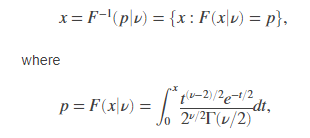

p=0.95    

p = 0.9500

k=3       %liczba stopni swobody

k = 3

yichi2 =chi2inv(p,k)

yichi2 = 7.8147

wizualizacja


k=3                 %liczba stopni swobody

k = 3

y=0:0.01:5*k

y =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



chi2 = chi2pdf(y,k)

chi2 =          0    0.0397    0.0559    0.0681    0.0782    0.0870    0.0948    0.1019    0.1084    0.1144    0.1200    0.1252    0.1301    0.1348    0.1392    0.1433    0.1473    0.1511    0.1547    0.1581    0.1614    0.1646    0.1676    0.1705    0.1733    0.1760    0.1786    0.1811    0.1835    0.1858    0.1881    0.1902    0.1923    0.1943    0.1963    0.1981    0.1999    0.2017    0.2034    0.2050    0.2066    0.2081    0.2096    0.2110    0.2124    0.2137    0.2150    0.2162    0.2174    0.2186



figure(6)
plot(y,chi2,'LineWidth',2)
hold on
grid on
title('Funkcja gęstości prawdopodobieństwa (pdf) rozkładu Chi-kwadrat')
xlabel('Y','Interpreter','latex')
ylabel('pdf','Interpreter','latex')

hold on
a = [yichi2  yichi2 ]

a =     7.8147    7.8147


b = [0 chi2pdf(yichi2 ,k)]

b =          0    0.0224



plot(a(2),b(2),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

t =0:0.01:yichi2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


chi2_p4 = chi2pdf(t,k);
area(t,chi2_p4 ,'FaceColor','g');
xticks(yichi2)


## Zastosowanie

Testy statystyczne dla populacji jednowymiarowej

**Test zgodności Chi-kwadrat **[[wiki]: test zgodności Chi-kwadrat](https://pl.wikipedia.org/wiki/Test_zgodno%C5%9Bci_chi-kwadrat)

150 razy rzucamy kostką do gry

n= [20 23 27 24 24 32]

H0: Zmienna Y  ma rozkład równomierny

H1:Zmienna Y  nie podlega rozkładowi równomiernemu

clear all
close all
clc
clearvars

p=0.95 %założone prawdopodobieństwo

p = 0.9500


alpha=1-p % poziom istotności

alpha = 0.0500



r=6 %liczba ścianek

r = 6


w=0 %nie szacujemy innych parametrow modelu

w = 0


k=r-w-1 %liczba stopni swobody k=5

k = 5


ykrytyczne= chi2inv(p,k) % krytyczna

ykrytyczne = 11.0705

[[wiki]:: test zgodności Chi-kwadrat](https://pl.wikipedia.org/wiki/Test_zgodno%C5%9Bci_chi-kwadrat)

Zliczenia


n= [20 23 27 24 24 32]

n =     20    23    27    24    24    32



pk=1/6 %prawdopodobieństwo rzutu kostką

pk = 0.1667


np=150/6 %150*pk - wartośc teoretyczna np=25

np = 25

suma=0;

for i=1:6
    suma=suma+ ((n(i)-np)^2)/np
end

suma = 1

suma = 1.1600

suma = 1.3200

suma = 1.3600

suma = 1.4000

suma = 3.3600

`Empiryczna wartośc statystyki testowej wynosi `$\chi^2 =3,36$ i jest mniejsza od obliczonej wartosci krytycznej czyli $\chi^2 =3,3600$ $\le$` ykrytyczne = 11,0705 to nie ma podstaw do odrzucenia hipotezy zerowej. Nie możemy więc na podstawie przeprowadzonego eksperymentu, twierdzić że kostaka jest nierzetelna.`

p = chi2cdf(suma,k)

p = 0.3553

`ponieważ p=0,3553 `$\ge$` alpha=1-p=0,05, nie ma więc podstaw do odrzucenia hipotezy zerowej`

`Dla innych wartości`

clear all
close all
clc
clearvars

n= [10 23 27 24 24 42]

n =     10    23    27    24    24    42


pk=1/6

pk = 0.1667

np=150/6

np = 25

suma=0;

for i=1:6
    suma=suma+ ((n(i)-np)^2)/np
end

suma = 9

suma = 9.1600

suma = 9.3200

suma = 9.3600

suma = 9.4000

suma = 20.9600


p=0.95

p = 0.9500

r=6

r = 6

w=0

w = 0

k=r-w-1

k = 5

nu=k

nu = 5

ykrytyczne = chi2inv(p,nu)

ykrytyczne = 11.0705


p = 1-chi2cdf(suma,k)

p = 8.2428e-04

`Empiryczna wartośc statystyki testowej wynosi `$\chi^2 =20,96$ i jest wieksza od obliczonej wartosci krytycznej czyli $\chi^2 =20,9600$ $>$` ykrytyczne = 11,0705 i dlatego są podstawy do odrzucenia hipotezy zerowej.Na podstawie przeprowadzonego eksperymentu, można podejrzewać że kostaka jest nierzetelna.`

Wizualizacja


figure (6)
y=0:0.1:40

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


p=0.95 %założone prawdopodobieństwo

p = 0.9500

r=6 %liczba ścianek

r = 6

w=0 %nie szacujemy innych parametrow modelu

w = 0

k=r-w-1 %liczba stopni swobody

k = 5

ykrytyczne = chi2inv(p,k)

ykrytyczne = 11.0705


ychi2=chi2pdf(y,k)

ychi2 =          0    0.0040    0.0108    0.0188    0.0275    0.0366    0.0458    0.0549    0.0638    0.0724    0.0807    0.0885    0.0959    0.1029    0.1094    0.1154    0.1209    0.1260    0.1306    0.1347    0.1384    0.1416    0.1444    0.1469    0.1489    0.1506    0.1519    0.1529    0.1536    0.1540    0.1542    0.1541    0.1537    0.1531    0.1523    0.1513    0.1501    0.1488    0.1473    0.1457    0.1440    0.1421    0.1402    0.1381    0.1360    0.1338    0.1315    0.1292    0.1269    0.1245


plot(y,ychi2,'LineWidth',2)
grid on
xlabel('y - obserwacje')
ylabel('Funkcja rozkładu prawdopodobieństwa (pdf) Chi-kwadrat')

hold on
a = [ykrytyczne ykrytyczne]

a =    11.0705   11.0705


b = [0 chi2pdf(ykrytyczne,k)]

b =          0    0.0193


plot(a(2),b(2),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)


Wyrysowanie punktu odpowiedającego otrzymanej statystyce

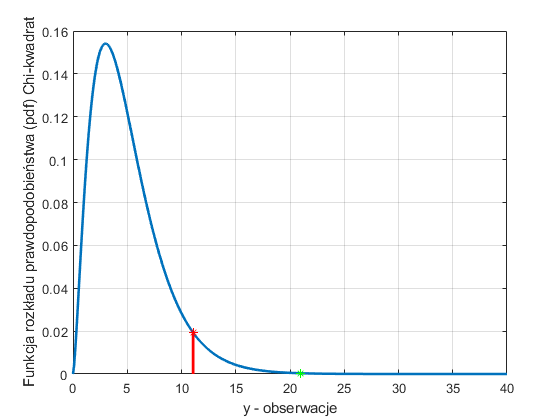

plot(suma,chi2pdf(suma,k),'g*')

Przykład 2

2 prawo Mendla

H0: Zmienna Y  spełnia 2 prawa Mendla

H1:Zmienna Y  nie spełnia 2 prawa mendla

n=2 %liczba klas

n = 2

lnasion=660 %liczba nasion

lnasion = 660

dpM= lnasion*[3/4 1/4] % 2 prawo Mendla

dpM =    495   165


[[wiki]::Prawa Mendla](https://pl.wikipedia.org/wiki/Prawa_Mendla)

Wyniki eksperymentu

eks=[510 150] %eksperyment

eks =    510   150


suma=0;
for i=1:n
    suma=suma+ ((eks(i)-dpM(i))^2)/dpM(i)
end

suma = 0.4545

suma = 1.8182


p=0.95 %założone prawdopodobieństwo

p = 0.9500

alpha=1-p % poziom istotności

alpha = 0.0500

k=n-1

k = 1

Obliczamy wartość krytyczną testu

ykrytyczne = chi2inv(p,k)

ykrytyczne = 3.8415

`Wartośc statystyki testowej wynosi `$\chi^2 =1,8182$

`ponieważ `$\chi^2 =1,8182$ $\le$` ykrytyczne =3,8415 to nie ma podstaw do odrzucenia hipotezy zerowej. Możemy założyć, że nasze doświadczenie spełnia 2 prawo Mendla.`

`Odchylenia istniejące między wynikami doświadczalnymi (empirycznymi) [510 150], a tymi kóre podaje teoria dpM=[495 165] są czysto przypadkowe i nie wpływają na interpretację doświadczenia (nie zaburzają naszego doświadczenia).`

Inne wyniki eksperymentu

eks=[330 330] %eksperyment

eks =    330   330


suma=0;
for i=1:n
    suma=suma+ ((eks(i)-dpM(i))^2)/dpM(i)
end

suma = 55

suma = 220


p=0.95 %założone prawdopodobieństwo

p = 0.9500

alpha=1-p % poziom istotności

alpha = 0.0500

k=n-1

k = 1

Obliczamy wartość krytyczną testu

ykrytyczne = chi2inv(p,k)

ykrytyczne = 3.8415

`Wartośc statystyki testowej wynosi `$\chi^2 =220$,0000

`ponieważ `$\chi^2 =220,0000$ $\ge$` ykrytyczne =3,8415 są podstawy do odrzucenia hipotezy zerowej. Możemy założyć, że takie doświadczenie nie spełnia drugiego prawa Mendla.`